k2 =      1


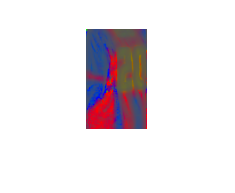

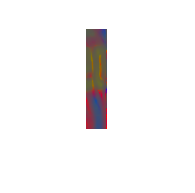

chiTotal =          0.642767862429033


k2 =      2


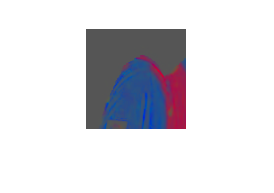

k =      1


total =           2.01352561273213


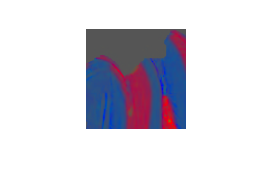

k =      1


total =           1.49406777606666


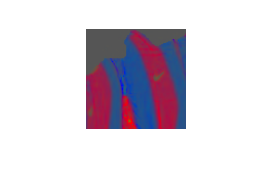

k =      1


total =           1.21458056354483


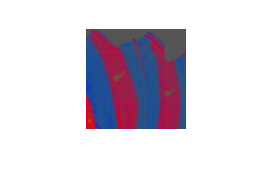

k =      1


total =           1.20122151421698


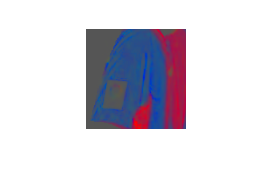

k =      1


total =           1.25255519990056


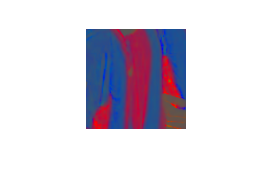

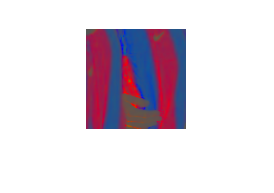

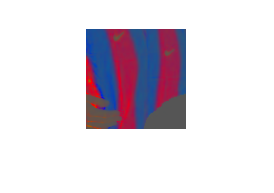

chiTotal =           0.96923213011416


k2 =      3


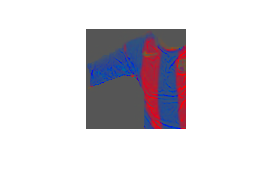

k =      1


total =           1.53498212906096


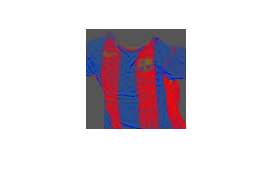

k =      1


total =           1.00857594864954


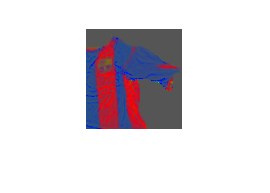

k =      1


total =           1.44326701882522


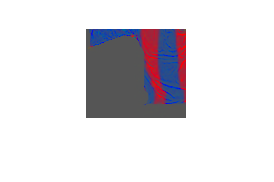

k =      1


total =           1.93672973883727


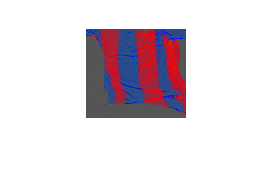

k =      1


total =           1.19226114981823


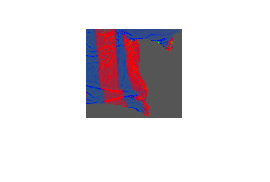

k =      1


total =           1.46814152789458


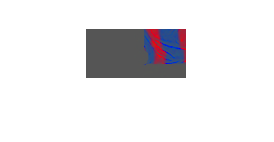

k =      1


total =           2.36904380844063


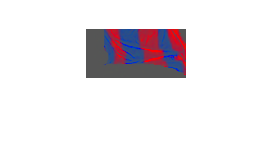

k =      1


total =            1.3840555467698


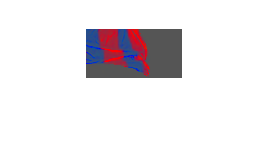

k =      1


total =           1.68762995789927


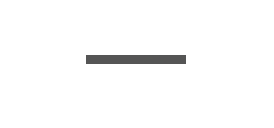

k =      1


total =            3.8959046590523


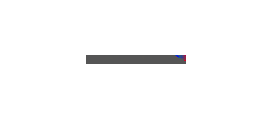

k =      1


total =           3.60226769456813


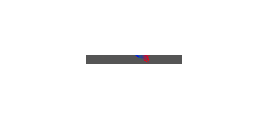

k =      1


total =           3.42371238599341


chiTotal =                 4294967296


k2 =      4


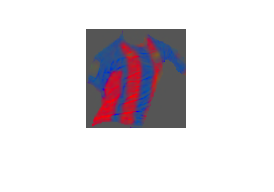

k =      1


total =           1.36975279932023


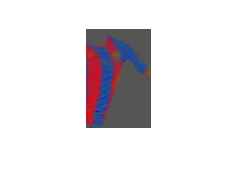

k =      1


total =            1.5631414593585


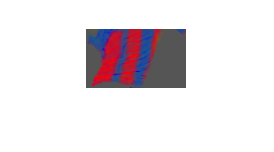

k =      1


total =           1.40802669069064


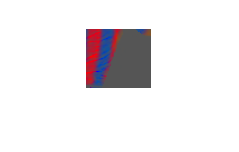

k =      1


total =           1.78210777670196


chiTotal =                 4294967296


k2 =      5


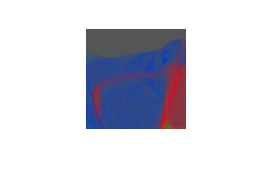

k =      1


total =           1.66419982718787


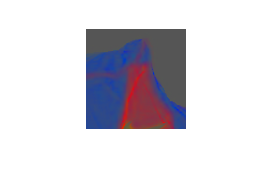

k =      1


total =           1.51037592428844


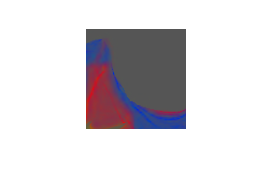

k =      1


total =           1.87406987582736


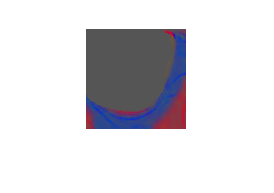

k =      1


total =           2.13923632729949


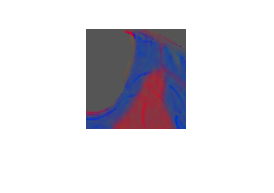

k =      1


total =           1.40711813261709


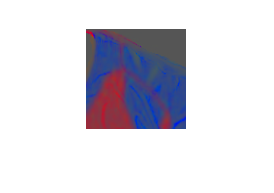

k =      1


total =           1.17650941664292


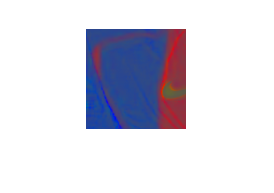

k =      1


total =           1.41697227343777


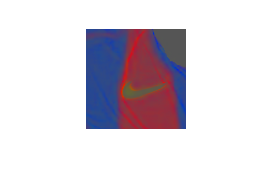

k =      1


total =           1.23470265433724


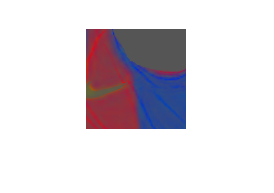

k =      1


total =           1.51743449187743


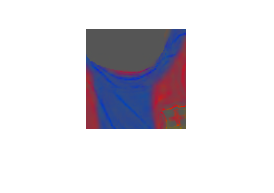

k =      1


total =           1.45112140817035


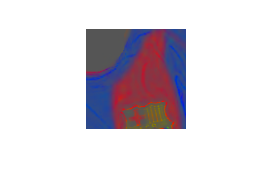

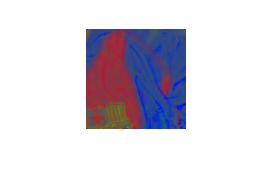

chiTotal =          0.840012375783119


k2 =      6


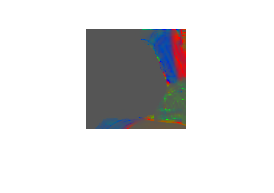

k =      1


total =           2.06320917938259


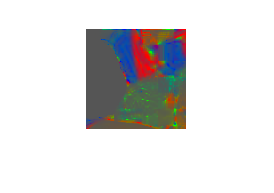

k =      1


total =           1.07602973914845


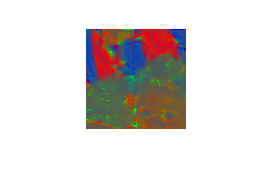

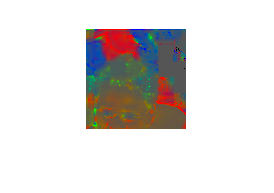

chiTotal =          0.564477592603428


k2 =      7


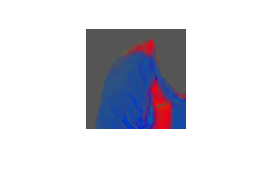

k =      1


total =           1.95925501650309


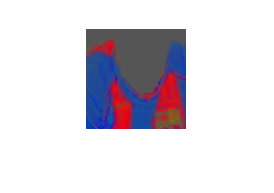

k =      1


total =           1.37618609062429


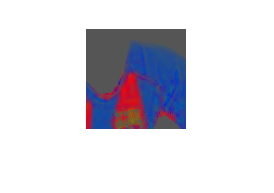

k =      1


total =           1.61796796645298


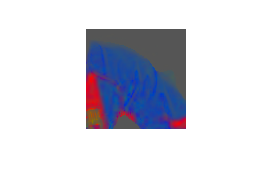

k =      1


total =           1.82664606335097


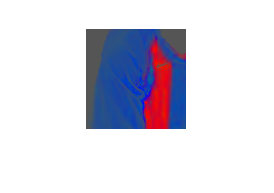

k =      1


total =           1.79446346695948


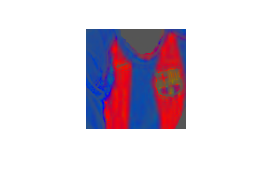

k =      1


total =           1.15021805345853


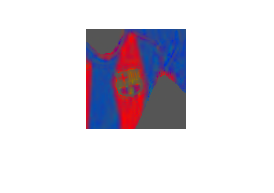

k =      1


total =           1.39833654400852


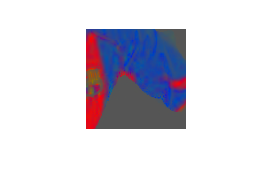

k =      1


total =           1.64592158874173


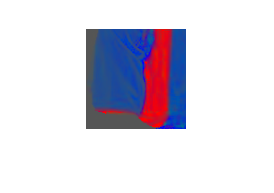

k =      1


total =           1.73897361869661


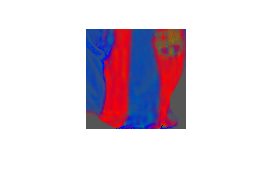

k =      1


total =           1.31892318401155


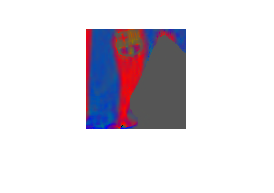

k =      1


total =           1.72721242225202


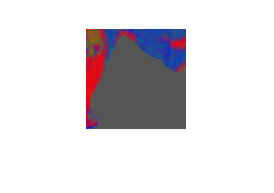

k =      1


total =           2.20155786072073


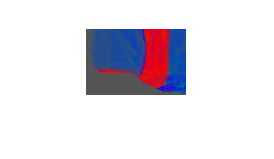

k =      1


total =           1.79107563938702


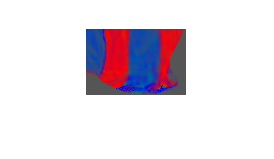

k =      1


total =           1.64999997587618


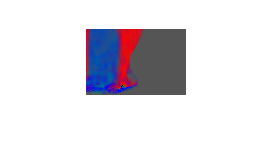

k =      1


total =           2.28697898177466


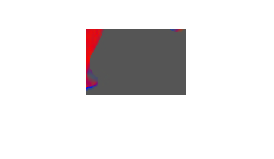

k =      1


total =           3.33989419772335


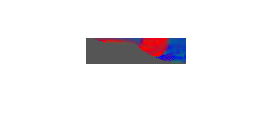

k =      1


total =           2.13592867633001


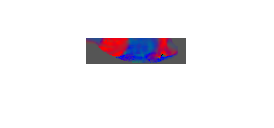

k =      1


total =           1.61586129048016


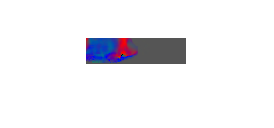

k =      1


total =           2.31228671683399


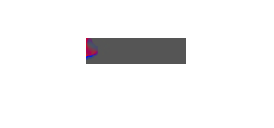

k =      1


total =           3.38498521237534


k =      1


total =    NaN


k =      1


total =    NaN


k =      1


total =    NaN


k =      1


total =    NaN


chiTotal =                 4294967296


k2 =      8


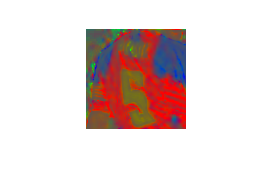

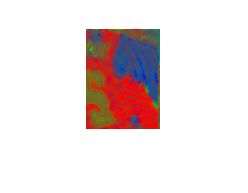

chiTotal =          0.743285064919322


k2 =      9


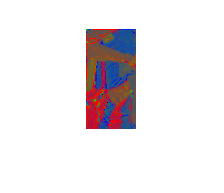

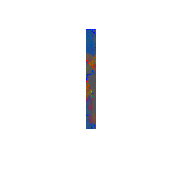

chiTotal =           0.74283547149917


k2 =     10


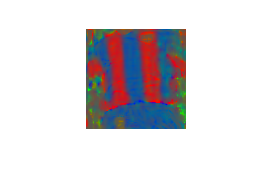

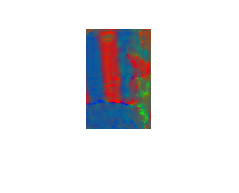

chiTotal =          0.665899015016071


clear
format long G
%imPrueba = imread('..\acmilan\01.jpg');
chiPrueba = 0;
for k2 = 1:10
    if k2 < 10
            imPrueba = imread(strcat( '0', int2str(k2) ,'.jpg'));
    else
            imPrueba = imread(strcat( int2str(k2) ,'.jpg'));
    end
    k2
    %figure
    %imshow(imPrueba)
    rTest = imPrueba(:,:,1);
    gTest = imPrueba(:,:,2);
    bTest = imPrueba(:,:,3);
    ITest = double(rTest)+double(gTest)+double(bTest);
    rTestn = uint8((double(rTest)./ITest)*255);
    gTestn = uint8((double(gTest)./ITest)*255);
    bTestn = uint8((double(bTest)./ITest)*255);
    rgbTestNormalizada = cat(3,rTestn,gTestn,bTestn);
    %imshow(rgbTestNormalizada), title('normalitzacio naive');
    
    
    chiTotal = 2^32;
    [h, w, d] = size(rgbTestNormalizada);
    %height_of_the_windows = fix(h/2);
    %width_of_the_windows = fix(w/2);
    %pasos_y = fix(height_of_the_windows/3);
    %pasos_x = fix(width_of_the_windows/3);
    height_of_the_windows = 100;
    width_of_the_windows = 100;
    pasos_y = 40;
    pasos_x = 40;
    
    for i = 1:pasos_y:(w-pasos_y)
        salida = 0;
        for j = 1:pasos_x:(h-pasos_x)
            height_of_the_windows_aux = height_of_the_windows;
            width_of_the_windows_aux = width_of_the_windows;
            if (i+height_of_the_windows> h)
                height_of_the_windows_aux = h-i;
            end
            if (j+width_of_the_windows> w)
                width_of_the_windows_aux = w-j;
            end
            
            subImagen = rgbTestNormalizada(i:(i+height_of_the_windows_aux-1),j:(j+width_of_the_windows_aux-1),:);
            figure
            imshow(subImagen)
            rTest = subImagen(:,:,1);
            gTest = subImagen(:,:,2);
            bTest = subImagen(:,:,3);
            rTestHisto = getHisto(rTest);
            gTestHisto = getHisto(gTest);
            bTestHisto = getHisto(bTest);
            
            %Empezamos comprobacion imagen
            for k = 1:1
                if k < 10
                    im = imread(strcat( '..\fuentes\' ,'0', int2str(k) ,'.jpg'));
                else
                    im = imread(strcat('..\fuentes\' ,int2str(k) ,'.jpg'));
                end
                %imshow(im)
                r = im(:,:,1);
                g = im(:,:,2);
                b = im(:,:,3);
                I = double(r)+double(g)+double(b);
                rn = double(r)./I;
                gn = double(g)./I;
                bn = double(b)./I;
                rgbNormalizada = cat(3,rn,gn,bn);
                %imshow(rgbNormalizada), title('normalitzacio naive')
                rHisto = getHisto(uint8(rn*255));
                gHisto = getHisto(uint8(gn*255));
                bHisto = getHisto(uint8(bn*255));
                
                rHisto = rHisto/sum(rHisto);
                gHisto = gHisto/sum(gHisto);
                bHisto = bHisto/sum(bHisto);
                rTestHisto = rTestHisto/sum(rTestHisto);
                gTestHisto = gTestHisto/sum(gTestHisto);
                bTestHisto = bTestHisto/sum(bTestHisto);
                
                chiR = distChi(rHisto,rTestHisto);
                chiG = distChi(gHisto,gTestHisto);
                chiB = distChi(bHisto,bTestHisto);
                total = chiR + chiB;
                if (total < 1)
                    i_total = i;
                    j_total = j;
                    i_total2 = (i+height_of_the_windows_aux-1);
                    j_total2 = (j+width_of_the_windows_aux-1);
                    chiTotal = total;
                    salida = 1;
                    break;
                end
                k
                total
            end
        end
        if(salida == 1)
            break;
        end
    end
    chiTotal
    if (chiTotal > chiPrueba)
        chiPrueba = chiTotal;
    end
end 

%i_total
%j_total
%chiR(i_total,j_total) 
%chiG(i_total,j_total) 
%chiB(i_total,j_total)
chiPrueba

chiPrueba =                 4294967296


%imshow(imPrueba(i_total:i_total2,j_total:j_total2,:))

function d = distChi(l1,l2)
    aux = (l1 == l2);
    l1 = l1 + double(aux);
    l2 = l2 + double(aux);
    d = sum(((l1-l2).^2)./(l1+l2));
end

function h = getHisto(im)
    h = zeros(1,256);
    [files cols] = size(im);
    for f=1:files
        for c=1:cols
            h(im(f,c)+1) = h(im(f,c)+1)+1;
        end
    end
end